# Archimedes螺旋线方程 & 画图


syms theta;
r = @(theta) 1 + 2.*theta;

theta0 = linspace(0,4*pi,200);
r0 = r(theta0);
x0 = r0.*cos(theta0);
y0 = r0.*sin(theta0);

plot(x0,y0); hold on;
scatter(0,0);
line([-30,30],[0,0],'Color','black');
line([0,0],[-30,30],'Color','black');
axis equal


## 螺旋线弧长计算

螺旋线的弧长计算公式为：


$$L=\int_{\theta_{1}}^{\theta_2} \sqrt{\left(r(\theta)\right)^{2}+\left(\frac{dr}{d\theta}\right)^{2}}d\theta$$


rTheta = diff(r,theta);
intFunc = matlabFunction(sqrt(sym(r).^2 + rTheta.^2),'Vars',theta);
L = integral(intFunc,0,4*pi)

## 弧长参数化方法测试1

a = 1;
b = 0.5;
syms s t;
r1 = [a.*cos(t);a.*sin(t);b.*t];
r2 = [a.*cos(s/sqrt(a^2+b^2));a.*sin(s/sqrt(a^2+b^2));b.*s/sqrt(a^2+b^2)];
tt = linspace(0,4*pi,1000);
L = sqrt(a^2 + b^2)*(tt(end) - tt(1));
rr1 = subs(r1,t,tt);
figure;
plot3(rr1(1,:),rr1(2,:),rr1(3,:));
hold on;
ss = linspace(0,L,30);
rr2 = subs(r2,s,ss);
scatter3(rr2(1,:),rr2(2,:),rr2(3,:));


[arc length parameterization of planar curve in Matlab](https://math.stackexchange.com/questions/809015/arc-length-parameterization-of-planar-curve-in-matlab)

实际上，他的办法就很朴素：给一个t的列表，然后计算t对应的每个位置的弧长，然后生成等距的弧长向量，再每个值回到弧长-参数列表里面查值；对于不是真好落在列表的数就用线性插值得到。

这个办法很粗暴但是胜在简单呀。我今晚就来实现一下这个叭，看看出来的结果误差有多大。

addpath(genpath('test'));
addpath(genpath('funcs'));
% t parameterizes the limacon x=(x(t),y(t)).
h=.1; t0 = 0; T = 2*pi+h;
t = t0:h:T;
r = t;
x = r.*cos(t);
y = r.*sin(t);

[tEq,fEq] = arclengthparam(t,[x;y],1);

% x_t0 = diff(x);
% y_t0 = diff(y);
x_t = derivative(x);
y_t = derivative(y);
% q_t = numericdiff([x;y],1,2);
s = cumtrapz( sqrt(x_t.^2 + y_t.^2 ) );

X = s.';
V = [ t.', x.', y.' ];
L = s(end);
s0 = s(1);
Xq = s0:1:L; % equally spaced indices
Vq = interp1(X,V,Xq); 
xs = Vq(:,2);
ys = Vq(:,3);

figure
% scatter(x,y);
hold on;
scatter(xs,ys);
axis equal

% 推广到连续积分？



## pdearcl函数

pp=pdearcl(p,xy,s,s0,s1) 返回参数化曲线的参数值，该参数化曲线对应于给定的一组弧长值。

- p是参数值的单调行向量（*monotone row vector*），xy是一个通过其两行给出曲线上对应点的矩阵。

- 曲线的第一点为弧长值s0，最后一点为弧长值s1。

- 返回时，pp包含与s中指定的弧长值相对应的参数值。

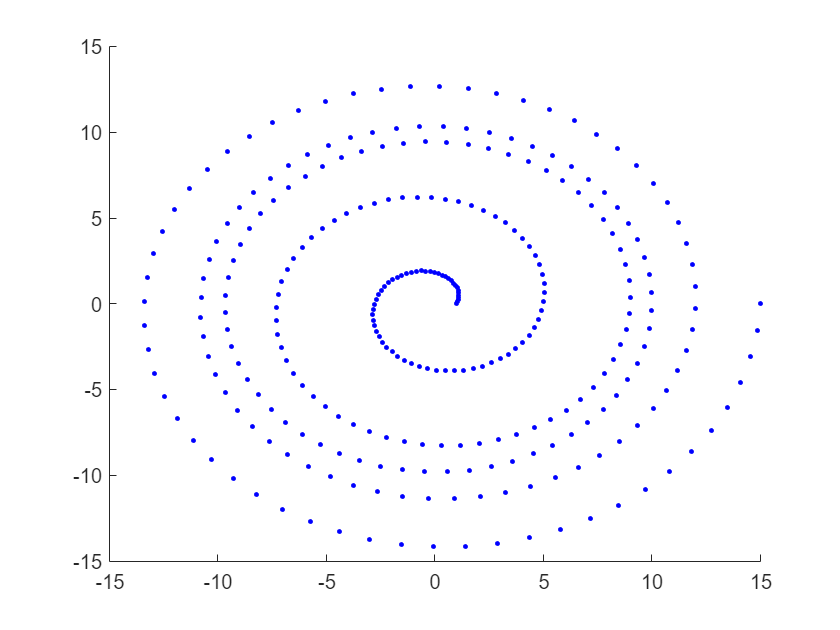

toolR = [1,5,9,10,12,15];
nLoop = length(toolR);
theta = linspace(0,2*(nLoop - 1)*pi,nLoop);
p = linspace(theta(1),theta(end),300);
r_theta = csape(theta,toolR,[1,1]);
R = fnval(r_theta,p);
xy(1,:) = R.*cos(p);
xy(2,:) = R.*sin(p);
figure;
scatter(xy(1,:),xy(2,:),6,'blue','filled');
hold on;


s0 = 0;
func = fncmb(fncmb(fnder(r_theta),'*',fnder(r_theta)),'+',fncmb(r_theta,'*',r_theta));
s1 = fnint(func,theta(end));

% s1 = int(func,t,theta(1),theta(end));
s = s0:1:s1;
pp = pdearcl(p,xy,s,s0,s1);


## My Project

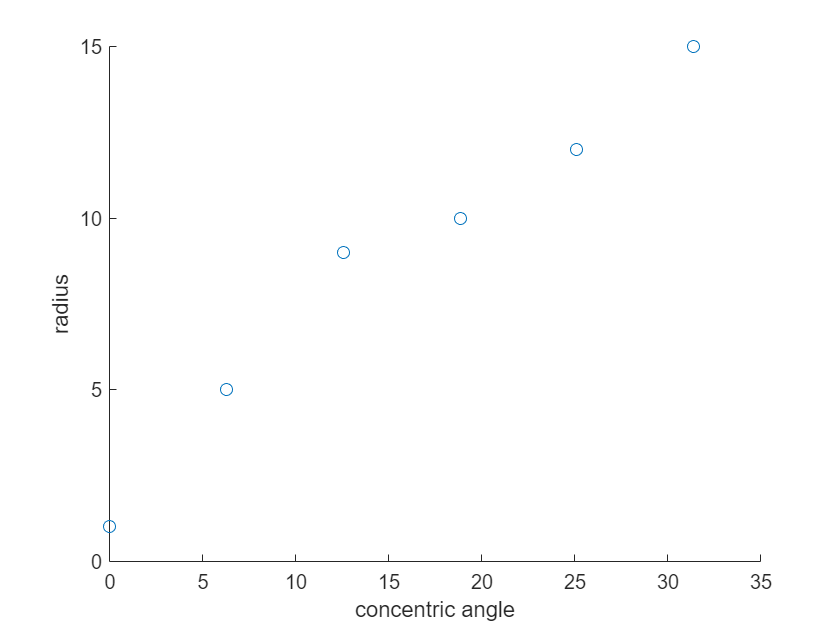

addpath(genpath('test'));
addpath(genpath('funcs'));
clear f0;

% load archimedes_r.mat; % toolR ptNum
toolR = [1,5,9,10,12,15];
nLoop = length(toolR);
theta = linspace(0,2*(nLoop - 1)*pi,nLoop);
figure;
scatter(theta,toolR); 
hold on;
xlabel('concentric angle');
ylabel('radius');

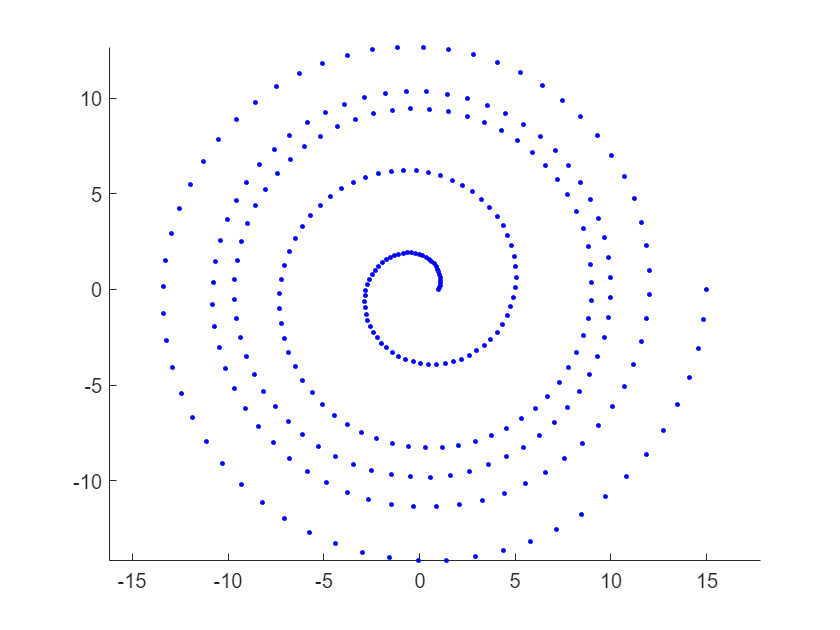

% figure
% plot(ptNum,toolR);

% get the r(theta) function in pp-form
r_theta = csape(theta,toolR,[1,1]);

% get the r(theta) function with polynomial interpolation

theta0 = linspace(theta(1),theta(end),300);
toolR0 = fnval(r_theta,theta0);
f0(1,:) = toolR0.*cos(theta0);
f0(2,:) = toolR0.*sin(theta0);
figure;
h1 = scatter(f0(1,:),f0(2,:),6,'blue','filled');
axis equal;

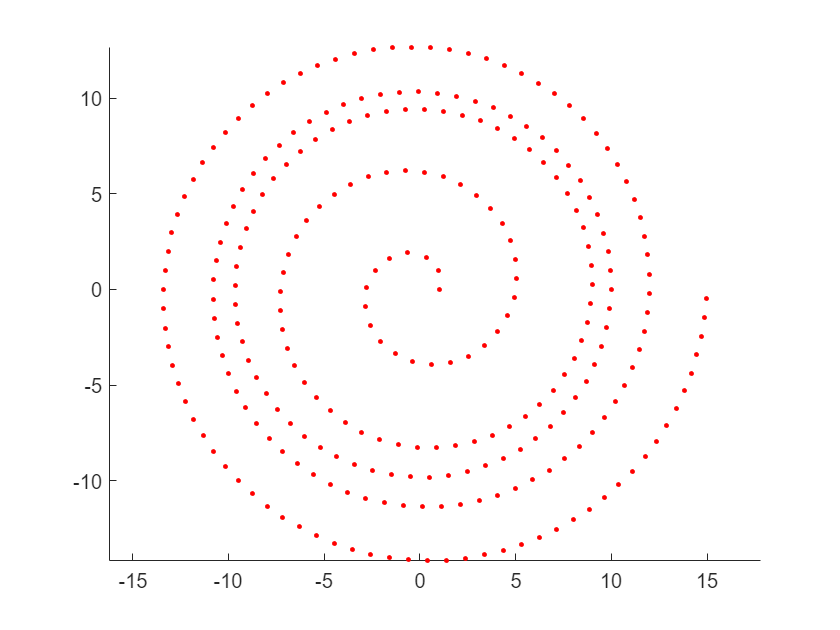


% get sample points with constant arc length
[tEq,fEq] = arclengthparam(theta0,f0,1,'interpType','linear');
figure;
h2 = scatter(fEq(1,:),fEq(2,:),6,'red','filled');
axis equal;

rmpath(genpath('test'));
rmpath(genpath('funcs'));